# Acoustic Setup for Object Localization

Student: Vinh Van

Student ID: 153042559

## **1. Introduction**

The problem is the local 3 foam cylinders inside a disk that have sound transmitters and reviewers around them. When sound hits these cylinders, we assume that there is no significant reflection or absorption; the signal is assumed to go in a straight line. Sound moving through the cylinder foam has a different velocity than moving in air. By measuring these different arrival times of sound signals, we can identify the location of these cylinders. 

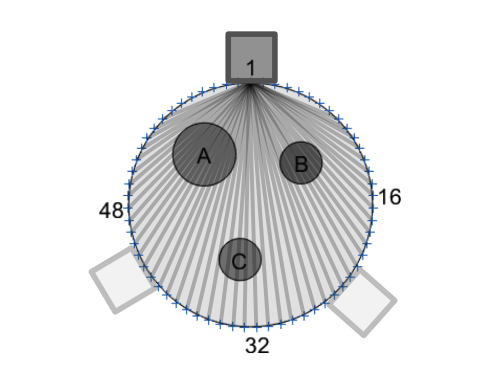

 The data provided in this problem include sound signal, recorded at 64 recivers from 3 transmiter at location 1, 24 and 43. These are also simulated data recorded without the cylinders. 

## **2. Materials and Methods**

For this probelm, we will solve it by the following main steps:

- **Estimate signal arival time**, from the recorded data. We will use **integration and AIC** methodfor this step.

- **Forward problem**: write algorithm to generate signal arival time data give coordinates of 3 cylinders. For this step we will use an modified implementation of the algorithms introduced in the **ground layers permittivitivity** problem of Lecture 3.

- **Backward problem**: from the recorded data, find the most likely coordinate of 3 cylinders. **Gibb sampling** is used for this step.

### **2.A. Estimate Signal Arival Time**

#### **2.A.1 Integration Method**

For the signal we compute it "energy", which can just be a square of that signal. The time of signal arival is the time t when the cumulated energy from t0 reach a certain threshold, e.g. 10% of total signal energy.

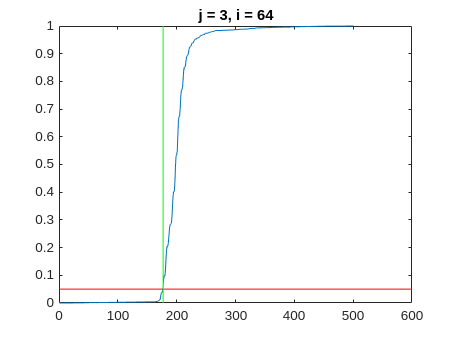

load measured_1_left.dat
load measured_24_left.dat
load measured_43_left.dat

signals{1} = measured_1_left;
signals{2} = measured_24_left;
signals{3} = measured_43_left;

arrival_time_list = zeros(192, 1);
count = 1;
figure;
for j = 1:3
    signal = signals{j};
    threshold = 0.05;
    for i = 1:64
        if max(signal(i,:)) == 0
            continue;
        end
        clf;
        energy = signal(i,:).^2;
        cum_sum_energy = cumsum(energy);
        cum_sum_energy = cum_sum_energy / max(cum_sum_energy);
        plot(cum_sum_energy);
        hold on;
        title(sprintf('j = %d, i = %d', j, i));
        % set x and y limits
        xlim([0 600]);
        ylim([0 1]);
        
        % draw a red line at 0.1
        plot([0 600], [threshold threshold], 'r');
        
        % draw a vertical line at the time of arrival
        arrival_time = find(cum_sum_energy > threshold, 1);
        arrival_time_list(count, :) = arrival_time;
        count = count + 1;
        plot([arrival_time arrival_time], [0 1], 'g');
        
        % plot(simulated_1*100);
        hold off;
        drawnow;
        pause(0.05)
    end
end

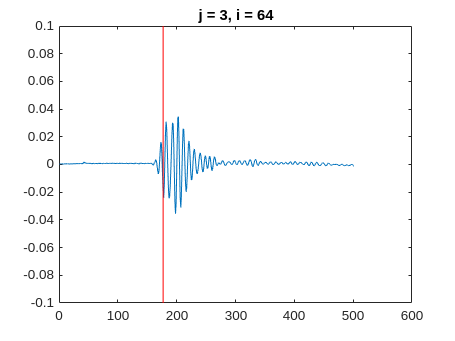

count = 1;
figure;
for j = 1:3
    signal = signals{j};
    for i = 1:64
        if max(signal(i,:)) == 0
            continue;
        end
        clf;
        plot(signal(i,:));
        hold on;
        title(sprintf('j = %d, i = %d', j, i));
        % set x and y limits
        xlim([0 600]);
        ylim([-0.1 0.1])
        
        % draw a vertical line at the time of arrival
        arrival_time = arrival_time_list(count, :);
        count = count + 1;
        plot([arrival_time arrival_time], [-100 100], 'r');
        
        hold off;
        drawnow;
        pause(0.05)
    end
end

**2.A.2 AIC Method**

Suppose there are two phrases of the signal, before the signal arive and after that. Each phrase has a diffrent variance, $\sigma_1$ and $\sigma_2$.  Then we find time k (phrase divider) with the minimun AIC (best model)

**AIC(k) = k*log(var(y(1:k))) + (nsamp–k -1)*(log(var(y(k+1:N))) **

more detail can be found here: [https://geoconvention.com/wp-content/uploads/abstracts/2011/058-Akaike_Information_Criterion_Applied_to_Microseismic_Data.pdf](https://geoconvention.com/wp-content/uploads/abstracts/2011/058-Akaike_Information_Criterion_Applied_to_Microseismic_Data.pdf) 

The algorithm is implemeted in:** aic_picker.m **

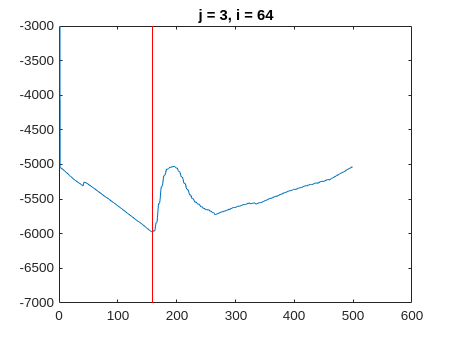

figure;
for j = 1:3
    signal = signals{j};
    for i = 1:64
        if max(signal(i,:)) == 0
            continue;
        end
        clf;
        [arrivalIndex, aic] = aic_picker(signal(i,:));
        
        plot(aic);
        hold on;
        title(sprintf('j = %d, i = %d', j, i));
        % set x and y limits
        xlim([0, 600]);
        ylim([-7000 -3000]);
        
        % draw a vertical line at the time of arrival
        plot([arrivalIndex arrivalIndex], [-7000 -3000], 'r');
        hold off;
        
        drawnow;
        pause(0.01)
    end
end

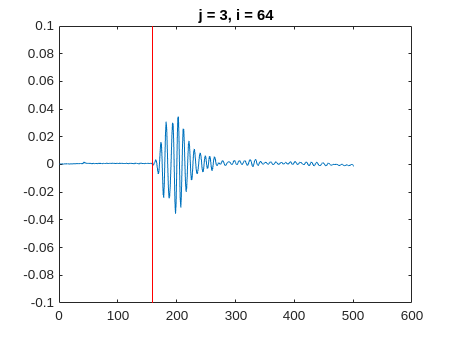

figure;
for j = 1:3
    signal = signals{j};
    for i = 1:64
        if max(signal(i,:)) == 0
            continue;
        end
        clf;
        [arrivalIndex, aic] = aic_picker(signal(i,:));
        
        plot(signal(i,:));
        hold on;
        title(sprintf('j = %d, i = %d', j, i));
        % set x and y limits
        xlim([0, 600]);
        ylim([-0.1 0.1]);
        % ylim([-7000 -3000]);
        
        % draw a vertical line at the time of arrival
        plot([arrivalIndex arrivalIndex], [-100 100], 'r');
        hold off;
        
        drawnow;
        pause(0.05)
    end
end

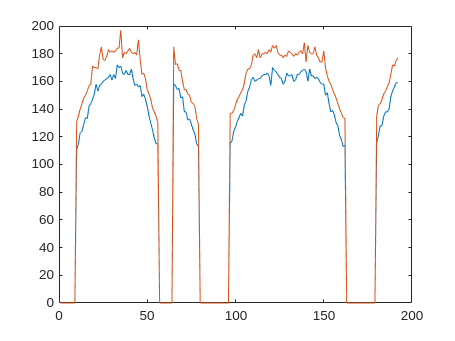

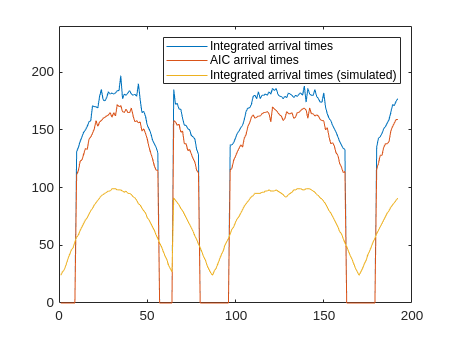

% Estimate arival time and save to file for using later
warning('off','all')
estimate_signal_arival_time

### **2.B. Forward Problem**

Similar to the bore hole problem, we have the equation dt = εds with ε as inverse of sound speed in the materials (air and foam). 

The forward matrix A is computed in** circle_ground_layer_matrix_with_comment.m**

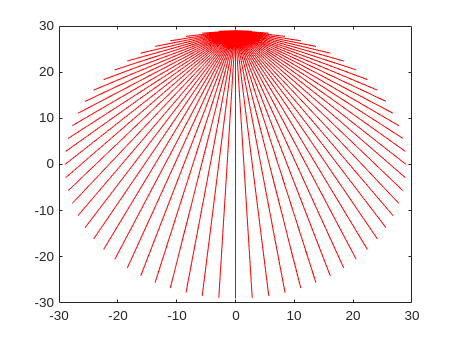

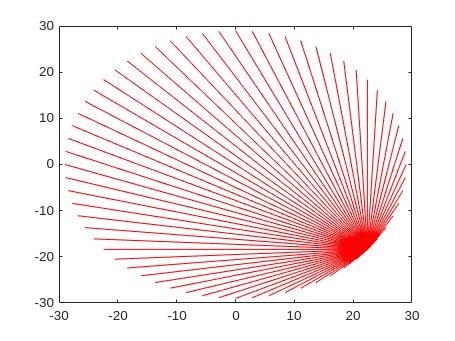

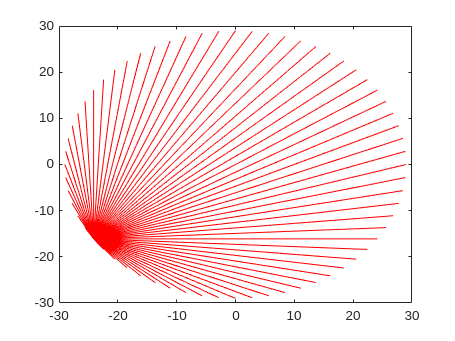

% Here we show the ray from each transmitter to recievers
circle_ground_layer_matrix_with_comment

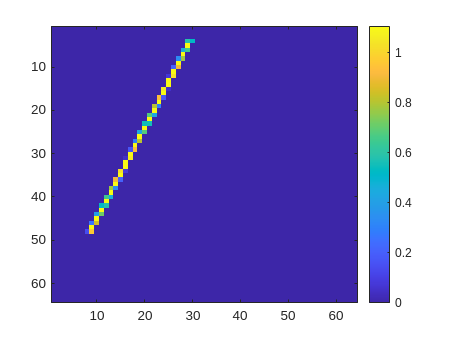


load sound_loc_matrix.mat A;
A = full(A);

% checking the rays
for i = 1:192
    ray = A(i,:);
    ray = reshape(ray, 64, 64);
    imagesc(ray);
    colorbar;
    pause(0.05);
end

Now we need to draw map given coordinates of the cylinders. Maps a draw by function **forward_map_of_x.m**

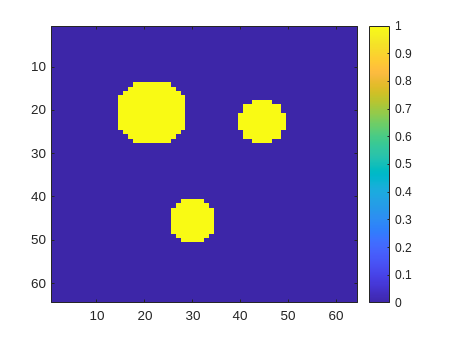

starting_point = [-11 ; 12 ; 12 ; 10; -2.5; -13];

[Ms, V] = forward_map_of_x(starting_point);

imagesc(reshape(Ms, 64, 64));colorbar;

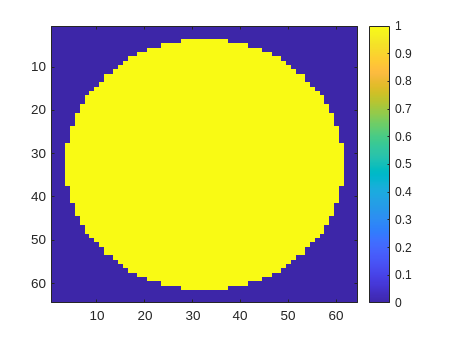

imagesc(reshape(V, 64, 64));colorbar;


% Ms is the map containing cylinder of the given coordinates.
% V is the map containing the area inside the disk.

% If the given cylinder coordinate violate the disk boundary, or overlap,
% the function will return square of large number as penalty.

The forward signal is then computed as:

### **measures = A * ( V * beta + Ms * alpha ) + offset**

- **measures**: forward signal

- **A**: forward matrix

- **V**: map of disk area

- **Ms**: map of cylinders of the given coordinates

- **beta**: inverse speed of sound signal in air

- **alpha**: inverse speed of sound signal in foam, in increment to speed in air.

- **offset**: time before the signal start

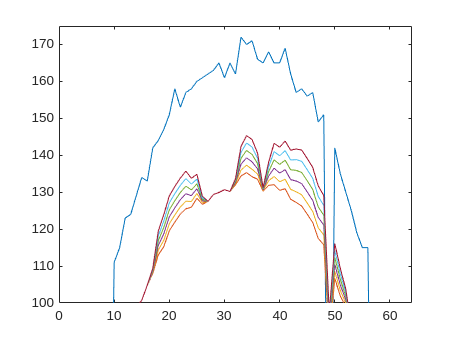

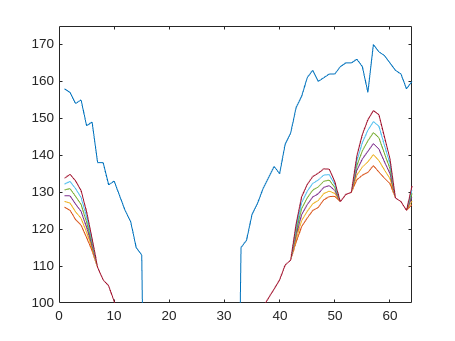

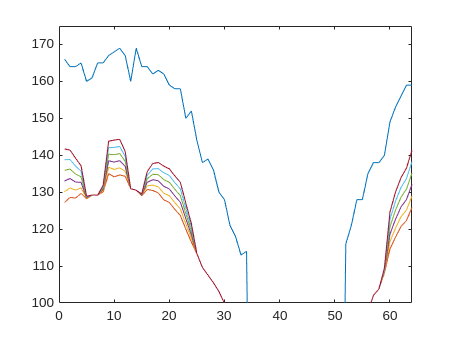

load aic_arival_times.mat aic_arival_times;
y = aic_arival_times;
% There is some problem with ray 49, likely cause by how approximation are
% done, so I drop it to reduce noisy data 
y(49) = 0;

starting_point = [-11 ; 12 ; 12 ; 10; -2.5; -13];

[Ms, V] = forward_map_of_x(starting_point);

beta = 1.4;

rs_y = reshape(y, 64, 3);

for i = 1:3
    figure;
    plot(rs_y(:,i));

    xlim([0 64])
    ylim([100 175])
    hold on

    measures = A * (V(:)*beta + Ms*0.4) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))

    measures = A * (V(:)*beta + Ms*0.6) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))

    measures = A * (V(:)*beta + Ms*0.8) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))

    measures = A * (V(:)*beta + Ms*1.0) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))

    measures = A * (V(:)*beta + Ms*1.2) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))

    measures = A * (V(:)*beta + Ms*1.4) + 50;
    rs_measures = reshape(measures, 64, 3);
    plot(rs_measures(:,i))


    hold off
end

Here we can see how alpha affect the forward signal. It amplify signal at the rays which go through the cylinders.

### **2.C. Backward Problem**

We use Gibb sampling to solve the backward problem. The individual sampling of each variable is implemented in 

- **Gibb_sampling_for_x.m**

- **Gibb_sampling_for_alpha.m**

- **Gibb_sampling_for_beta.m**

- **Gibb_sampling_for_offset.m**

To do sampling on all variable is very unstable, we can use the simulated data to estiI hav emate beta, and thus need not to sampling for it. 

*** An important insight is that, larger alpha is very helpful to stabalize the sampling process. Because for large alpha, the signal invole of the cylinders are more amplified, which help match it with the measured real data. Even if alpha is overly large, the smallest error are still archived when the cylinders is at the right coordinate, because at that point, the diffrent between measured real data and our forwarded measure is still the smallest in the search space. We will set alpha = 1

**Now we will do  Gibb sampling using the simulated data, for calibrating beta**

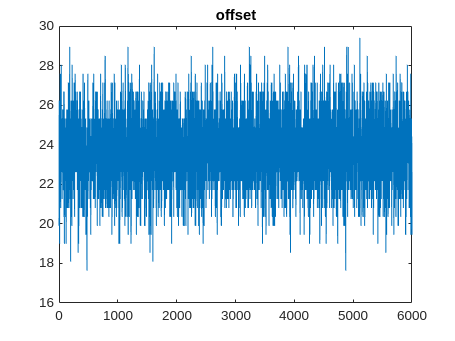

load intergrated_arival_times.mat intergrated_arival_times;
load aic_arival_times.mat aic_arival_times;
load intergrated_arival_times_simulated.mat intergrated_arival_times_simulated;

sigma = 10;
iterations = 6000;

starting_beta = 1.5;

load sound_loc_matrix.mat A;
A = full(A);

%%% SET OBSERVATIONS
y = intergrated_arival_times_simulated;
y(49) = 0;
contain_measure_idxs = (y~=0);

v = y(contain_measure_idxs, :);
A = A(contain_measure_idxs, :);

x = starting_point;
beta = starting_beta;

% Pre-allocate a matrix to store all the sampled points (each column is a sample)
betas = zeros(1, iterations);
offsets = zeros(1, iterations);

% Store the initial point in the first column
betas(:,1) = starting_beta;

% Begin the Gibbs sampling loop:
for k = 1 : iterations
    % k

    for p = 1:6
        alpha = 0; % there would be no cylinder anyway
        offset = Gibb_sampling_for_offset(x, A, v, sigma, alpha, beta);
        beta = Gibb_sampling_for_beta(x, A, v, sigma, offset, alpha);
    end
    
    % Store the updated sample (new position) in the Points matrix.
    betas(:,k) = beta;
    offsets(:,k) = offset;
end

figure;
plot(1:size(offsets, 2), offsets(1,:))
title("offset")

% offset samples have converged, but this offset is only for the simulated
% data, and can not be applied to the real measured data

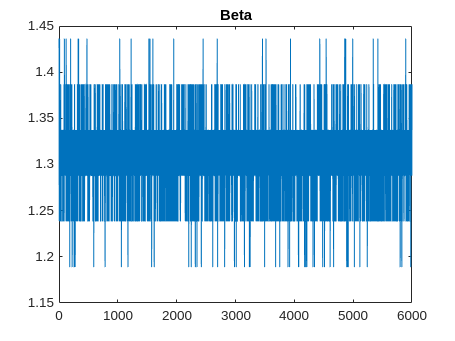

figure;
plot(1:size(betas, 2), betas(1,:))
title("Beta")

By this plot, **we will try beta in [1.25, 1.4]**

## **3. Results**

We are now ready to run Gibb samping for cylinders coordinate, and offset using the real measured data. Parameter alpha = 1 and beta is set in [1.25, 1.4]

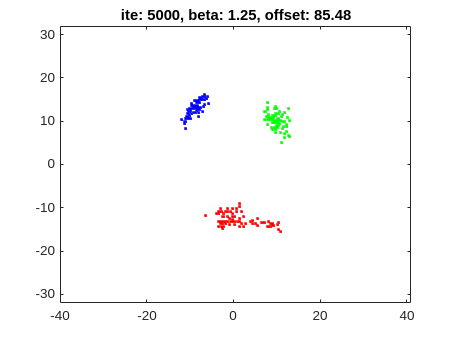

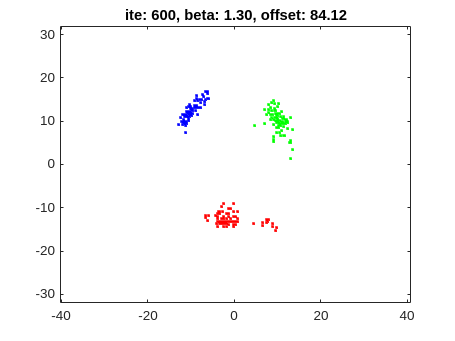

load intergrated_arival_times.mat intergrated_arival_times;
load aic_arival_times.mat aic_arival_times;
load intergrated_arival_times_simulated.mat intergrated_arival_times_simulated;

sigma = 5;
iterations = 5000;
burn_in = 1000;
gibbs_res = 100;
disk_radius = 29;

starting_point = [0 ; 0 ; 0 ; 14; -15; 0];

load sound_loc_matrix.mat A;
A = full(A);

%%% SET OBSERVATIONS
y = aic_arival_times;
y(49) = 0;
contain_measure_idxs = (y~=0);
v = y(contain_measure_idxs, :);
A = A(contain_measure_idxs, :);

collect_points = [];

alpha = 1;
for beta = linspace(1.25, 1.4, 4)
figure();
x = starting_point;
Points = zeros(6, iterations);
offsets = zeros(1, iterations);
Points(:,1) = [x];


for k = 1 : iterations
    for p = 1:6
        offset = Gibb_sampling_for_offset(x, A, v, sigma, alpha, beta);
        x = Gibb_sampling_for_x(x, p, A, v, sigma, gibbs_res, alpha, beta, ...
                                    disk_radius, offset);
    end
    
    Points(:,k) = x;
    offsets(:,k) = offset;

    if mod(k, 100) == 0
        % k
        clf;
        plot(Points(1, k-99:k), Points(2, k-99:k), 'b.');
        hold on;
        plot(Points(3, k-99:k), Points(4, k-99:k), 'r.');
        plot(Points(5, k-99:k), Points(6, k-99:k), 'g.');
        xlim([-32 32])
        ylim([-32 32])
        title(sprintf('ite: %d, beta: %.2f, offset: %.2f', ...
                        k, beta, offset))
        axis equal;
        hold off;
        drawnow;
    end
end
collect_points = [collect_points; Points];
end

The results of beta 1.25 and beta 1.3-1.4 if diffrent, let's inspect which result is better.

k = size(collect_points, 2);

points_1_25 = collect_points(1:6,:);
figure; clf;
hold on;
plot(points_1_25(1, k-1000:k), points_1_25(2, k-1000:k), 'b.');
plot(points_1_25(3, k-1000:k), points_1_25(4, k-1000:k), 'r.');
plot(points_1_25(5, k-1000:k), points_1_25(6, k-1000:k), 'g.');
cm_point_1_25 =  mean(points_1_25, 2);
scatter(cm_point_1_25(1), cm_point_1_25(2), 'c', 'linewidth',5);
scatter(cm_point_1_25(3), cm_point_1_25(4), 'm', 'linewidth',5);
scatter(cm_point_1_25(5), cm_point_1_25(6), 'y', 'linewidth',5);
xlim([-32 32])
ylim([-32 32])
title(sprintf('beta: %.2f', 1.25))
hold off;

points_1_40 = collect_points(19:24,:);
figure; clf;
hold on;
plot(points_1_40(1, k-1000:k), points_1_40(2, k-1000:k), 'b.');
plot(points_1_40(3, k-1000:k), points_1_40(4, k-1000:k), 'r.');
plot(points_1_40(5, k-1000:k), points_1_40(6, k-1000:k), 'g.');
cm_point_1_40 =  mean(points_1_40, 2);
scatter(cm_point_1_40(1), cm_point_1_40(2), 'c', 'linewidth',5);
scatter(cm_point_1_40(3), cm_point_1_40(4), 'm', 'linewidth',5);
scatter(cm_point_1_40(5), cm_point_1_40(6), 'y', 'linewidth',5);
xlim([-32 32])
ylim([-32 32])
title(sprintf('beta: %.2f', 1.4))
hold off;

% Here we have 2 solutions
load sound_loc_matrix.mat A;
A = full(A);
y = aic_arival_times;

[Ms, V] = forward_map_of_x(cm_point_1_25);
measures = A * (V(:)*1.25 + Ms*1) + 85;
figure; clf;
plot(measures, 'DisplayName', 'forward')
hold on;
plot(y, 'DisplayName', 'real data');
xlim([0 192])
ylim([100 185])
title(sprintf('beta: %.2f', 1.25))
legend('NumColumns',2);
hold off;


[Ms, V] = forward_map_of_x(cm_point_1_40);
measures = A * (V(:)*1.4 + Ms*1) + 80;
figure; clf;
plot(measures, 'DisplayName', 'forward')
hold on;
plot(y, 'DisplayName', 'real data');
xlim([0 192])
ylim([100 185])
title(sprintf('beta: %.2f', 1.4))
legend('NumColumns',2);
hold off;

We can see that the shape of cm_point_1_40 fit the shape of real data much better, compared to cm_point_1_25. **Therefor, we choose cm_point_1_40 as our solution to this problem.**

cm_point_1_40

Which is quite near to the true solution. 

true_solution = [-11 ; 12 ; 12 ; 10; -2.5; -13];
true_solution
diff = abs(true_solution - cm_point_1_40);
diff

## **4. Discussion**

I have try to do Gibb sampling on cylinders' coordinates,  alpha, beta, offset, but the sampling sequence is very unstable and do not converge. So infer beta using the simulated data is needed. Also, the impact of large alpha is very significant, because if alpha is small, the affect of cylinders' coordinates is mixed up with noise, and the sequence become unstable. Additionally, beta decides the how stretch out the forward signal is in the vertical direction, and it need to be at the right level, as we have seen, it have critical impart on the sampling sequence convergent points.

With setted beta and large alpha, we just need to do sampling for cylinders' coordinates and offset.  The Gibb sampling sequence for these variables is usually very stable.